# Data preprocessing using LiveTasks

Some noisy experimental data;

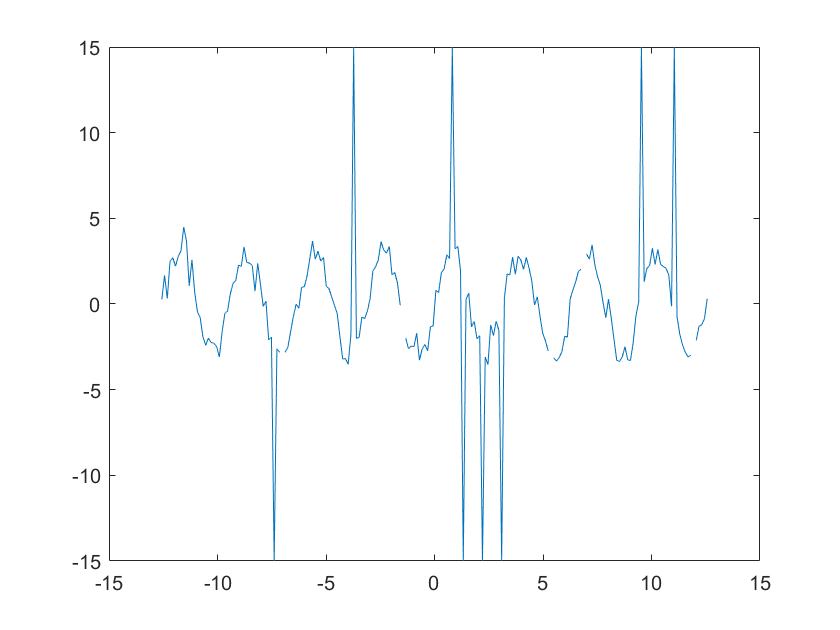

noise=0.5*randn(1,200);
x=linspace(-4*pi,4*pi,200);
y=3*sin(2*x)+noise;

ind=[45,89,143,155,195];
y(ind)=NaN;
y(randi(200,1,4))=15;
y(randi(200,1,4))=-15;
plot(x,y)

The data contains missing data points and outliers as well. Before we analyze the data we should clean up the data set.

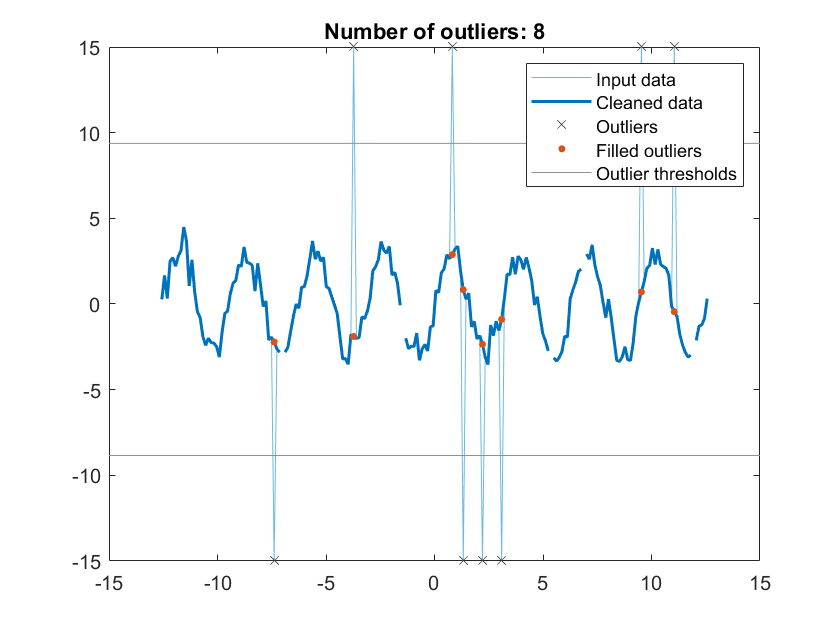

% Fill outliers
[cleanedData,outlierIndices,thresholdLow,thresholdHigh] = filloutliers(y,...
    'pchip','SamplePoints',x);

% Visualize results
clf
plot(x,y,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(x,cleanedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(x(outlierIndices),y(outlierIndices),'x','Color',[64 64 64]/255,...
    'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices))])

% Plot filled outliers
plot(x(outlierIndices),cleanedData(outlierIndices),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled outliers')

% Plot outlier thresholds
plot([xlim missing xlim],[thresholdLow*[1 1] NaN thresholdHigh*[1 1]],...
    'Color',[145 145 145]/255,'DisplayName','Outlier thresholds')

hold off
legend

clear outlierIndices thresholdLow thresholdHigh


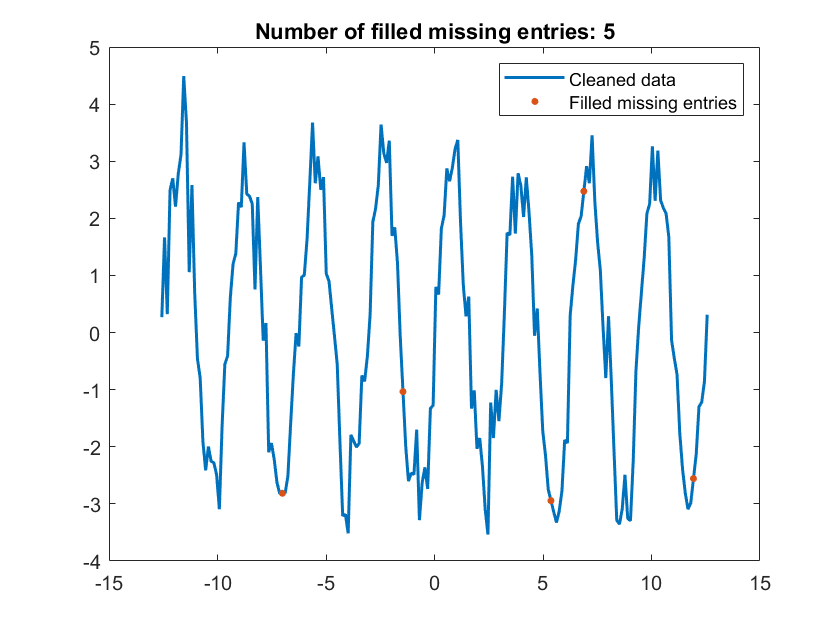

% Fill missing data
[cleanedData2,missingIndices] = fillmissing(cleanedData,'linear',...
    'SamplePoints',x);

% Visualize results
clf
plot(x,cleanedData2,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')
hold on

% Plot filled missing entries
plot(x(missingIndices),cleanedData2(missingIndices),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled missing entries')
title(['Number of filled missing entries: ' num2str(nnz(missingIndices))])

hold off
legend

clear missingIndices


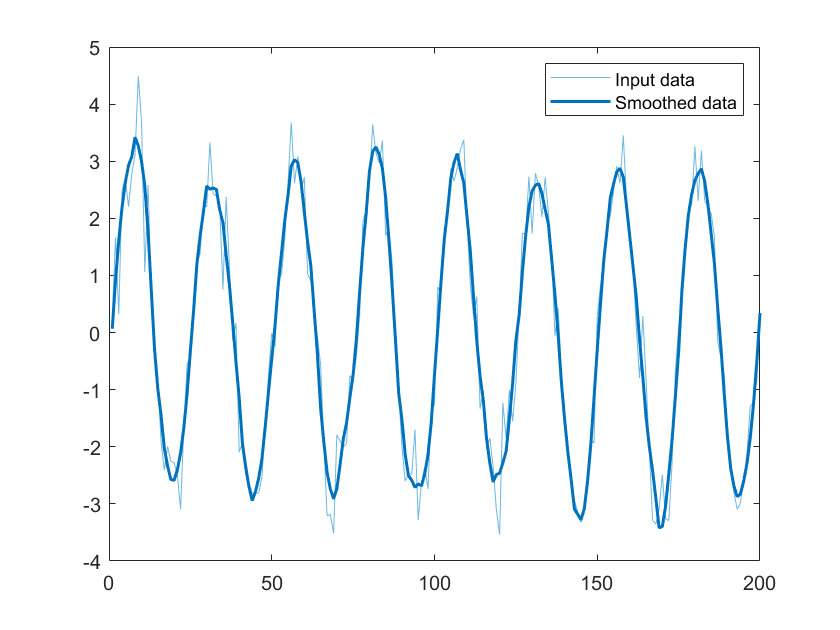

% Smooth input data
smoothedData = smoothdata(cleanedData2,'sgolay','SmoothingFactor',0.25);

% Visualize results
clf
plot(cleanedData2,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(smoothedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend

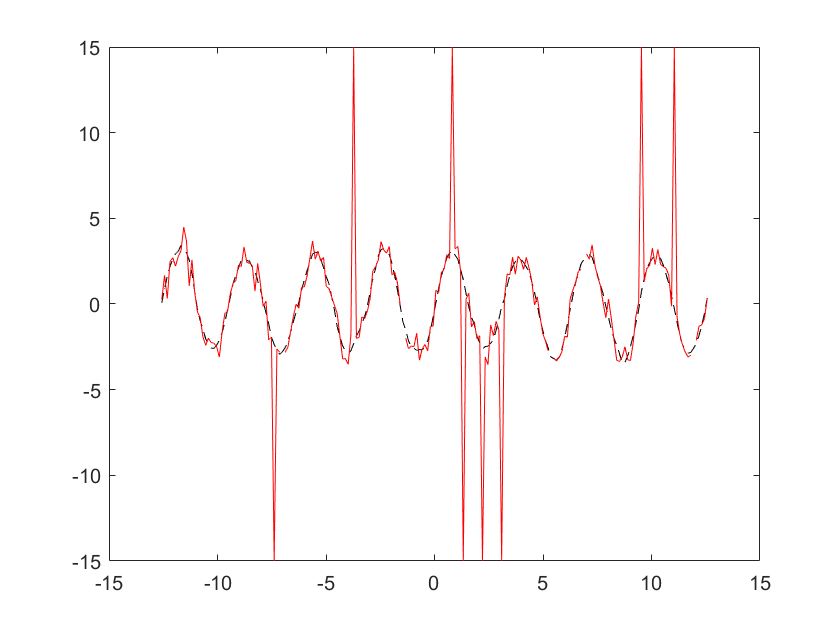

plot(x,smoothedData,'k--',x,y,'r-')